# Classify Credit Ratings

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads and displays the credit ratings data and a 7-fold cross-validated tree model of `creditRatings`.

rng(0)
creditRatings = readtable("./data/creditRatings.csv")

creditRatings = 250×6 table
    WC_TA     RE_TA     EBIT_TA    MVE_BVTD    S_TA     Rating 
    ______    ______    _______    ________    _____    _______

     0.517     0.349     0.109       1.19      0.149    {'BBB'}
     0.169     0.274      0.07      0.536      0.131    {'BB' }
     0.536     0.863     0.107      4.549      0.583    {'AAA'}
     0.313     0.511     0.078      3.461      0.452    {'AA' }
    -0.029     0.081     0.028      0.971      0.226    {'BB' }
      -0.1    -0.703     0.025      0.066       0.06    {'CCC'}
     0.215     0.444     0.057        3.1      0.392    {'AAA'}
     0.376     0.492     0.094       2.51      0.355    {'AA' }
     0.117      0.18     0.042       1.95      0.523    {'A'  }
     0.004     0.081     0.028      0.498      0.124    {'BB' }

creditRatings.Rating = categorical(creditRatings.Rating);
cvpt = cvpartition(creditRatings.Rating, "KFold", 7);
mdlFull = fitctree(creditRatings, "Rating", "CVPartition", cvpt);
fullLoss = kfoldLoss(mdlFull)

fullLoss = 0.3400

## Task 1

Fit model with 3 or fewer predictors.

**Method: Feature Selection (Tree)**

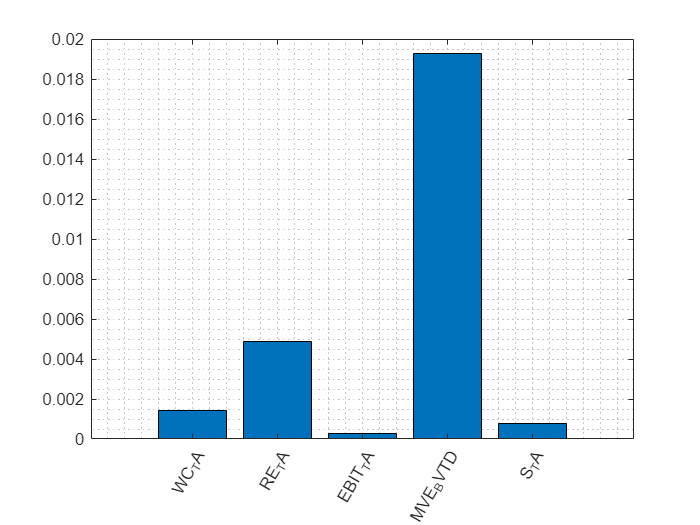

tModel = fitctree(creditRatings, "Rating");
p = predictorImportance(tModel);

% View predictor importance on a bar plot
bar(p)
grid minor
xticklabels(creditRatings.Properties.VariableNames(1:end-1))
xtickangle(60)


% Sort out the top predictors
[~, iSorted] = sort(p);
selected = [iSorted(1:2) width(creditRatings)];

% Create tree model to reduced data
mdl = fitctree(creditRatings(:, selected), "Rating", "KFold", 7);
mdlLoss = kfoldLoss(mdl)

mdlLoss = 0.5040

**Method: Feature Transformation (PCA)**

[pcs, scrs, ~, ~, pexp] = pca(creditRatings{:, 1:end-1});
% Create tree model to reduced data
mdl = fitctree(scrs(:, 1:3), creditRatings.Rating, "KFold", 7);
mdlLoss = kfoldLoss(mdl)

mdlLoss = 0.3440

## Task 2

Fit ensemble with 3 or fewer predictors.

**Method: Feature Selection (Tree)**

mdlEns = fitcensemble(creditRatings(:, selected), "Rating", "Method", "Bag",...
    "NumLearningCycles", 50, "Learners", "tree", "KFold", 7);
lossEns = kfoldLoss(mdlEns)

lossEns = 0.5440

**Method: Feature Transformation (PCA)**

mdlEns = fitcensemble(scrs(:, 1), creditRatings.Rating, "Method", "Bag",...
    "NumLearningCycles", 50, "Learners", "tree", "KFold", 7);
lossEns = kfoldLoss(mdlEns)

lossEns = 0.4080